测试集数据生成，根据dolphin测量数据生成差异RTdose文件以及Mat文件

执行该代码前需要将测量的orim文件以及错误计划引入文件和对应需要提取的勾画结构信息Rt structure放置于同一个文件夹内

clear
close all

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%创建后面剂量差异信息的文件命名格式
FileName = ["LAT-1mmL";"LAT-1mmR";"Lng-1mmF";"Lng-1mmH";"Vrt-1mmA";"Vrt-1mmP"...
            ;"MU3%-";"MU3%";"MU5%-";"MU5%";"p1--0.2G";"p1--0.4G";"p1-0.2G";"p1-0.4G"...
            ;"p1--0.5X2F";"p1--1X2F";"p1-0.5X2F";"p1-1X2F";"p1-0.5X2R";"p1-1X2R";"p1-2X2R"...
            ;"p1-AXBW";"p1-AAA";"p1-AXB";"p1-body0.5";"p1-body1.5";"p1-body1";"P1-B0.5";"P1+B0.5";"P1-B1";"P1+B1"];

FileName_SIZE = size(FileName,1);%获取需要处理文件名数组的长度

%7分类问题
SETUP = ["LAT-1mmL";"LAT-1mmR";"Lng-1mmF";"Lng-1mmH";"Vrt-1mmA";"Vrt-1mmP"];
MU = ["MU3%-";"MU3%";"MU5%-";"MU5%"];
MLCR = ["p1-0.5X2R";"p1-1X2R";"p1-2X2R"];
MLCS = ["p1--0.5X2F";"p1--1X2F";"p1-0.5X2F";"p1-1X2F"];
GANTRY = ["p1--0.2G";"p1--0.4G";"p1-0.2G";"p1-0.4G"];
ErrorFree = ["p1-AXBW";"p1-AAA";"p1-AXB"];
BodyChanges = ["p1-body0.5";"p1-body1.5";"p1-body1"];
BladderChanges = ["P1-B0.5";"P1+B0.5";"P1-B1";"P1+B1"];

%%%打开文件选择病人ID的文件夹中的任意文件即可
[filename,filepath] = uigetfile('*.*','Please select a file to improt','D:\医学物理\待投稿论文\Dosiomics\dophinCOMPUTE\TESTDATA');
%只搜索DCM文件
filetype = '*.dcm';
searchmode = fullfile(filepath,filetype);
folders = dir(searchmode);
folder_len = size(folders,1);%获取文件目录长度

%遍历文件找到RS的路径读取，并在folder中删除只剩下RD文件
for i = 1:folder_len
    if contains(folders(i).name,'RS')
        filename = fullfile(folders(i).folder,folders(i).name);
        %fprintf('正在读取 DICOM 文件 %s\n', filename) 
        %{ 
          **`UseVRHeuristic`参数**：当设置为`false`时，MATLAB将严格按照DICOM标准解析文件，而不尝试猜测VR类型。
         这可以避免因启发式方法导致的错误。**影响**：关闭启发式方法可能会使MATLAB无法读取一些不符合标准但实际可读的文件。
         但对于大多数标准文件，这样设置没有问题。**其他注意事项**：如果文件确实不符合标准，可能需要使用第三方工具修复DICOM文件。
        %}
        RSinfo = dicominfo(filename,UseVRHeuristic=false); %读取RS文件 如果警告：字节 1679728 处的属性(3006,0040)可能错误地解释为显式 VR建使用此代码
        %RSinfo=dicominfo(filename);
        %记住RS当前的行号信息
        rs_row_to_delete = i;
    end
end
folders(rs_row_to_delete) = [];  %删除当前的RS的文件目录，只剩下dose文件 RS和P1-orim不能同时处理 由于删除元素会更改数目索引
%因此分开处理

folder_len = size(folders,1);%更新文件目录长度
for i = 1 : folder_len
    if contains(folders(i).name,'orim')
        filename = fullfile(folders(i).folder,folders(i).name);
        info_ori = dicominfo(filename);
        dose_ori = dicomread(filename);
        size_ori = size(dose_ori);
        %记住当前ori的行号信息
        ori_row_to_delete = i;
    end
end
folders(ori_row_to_delete) = [];  %删除当前的参考p1-orim的文件目录，只剩下其他RD文件

%当头颈部请注释后续代码

%{
folder_len = size(folders,1);%更新文件目录长度
for i = 1 : folder_len
    if contains(folders(i).name,'Bori')
        filename = fullfile(folders(i).folder,folders(i).name);
        info_Bori = dicominfo(filename);    %bladder原始剂量文件导入
        dose_Bori = dicomread(filename);
        size_Bori = size(dose_Bori);
        %记住当前ori的行号信息
        Bori_row_to_delete = i;
    end
end
folders(Bori_row_to_delete) = [];  %删除当前的参考p1-Bori的文件目录，只剩下其他RD文件
%}


## 剂量相减计算差异diff-dose

%新建差异文件夹用于保存数据
newfile = "diff";
newfilepath = fullfile(filepath,newfile);
[status, msg, msgID] = mkdir(newfilepath);

folder_len = size(folders,1); %在更新获取文件长度

%%%开始读取文件剂量剂量差异
for i = 1 : folder_len
    newfile = fullfile(folders(i).folder,folders(i).name);%逐个读取逐个计算
    info_new = dicominfo(newfile);
    
    %裁剪数据
    fprintf("开始计算%s剂量差异分布!\n       \n",folders(i).name);

    %调用子函数 尺寸匹配重采样计算公共区域的差异剂量
    [dosediff, diff_info] = cal_diff(info_ori, info_new);

    %%%%%———————————  形成224X224X224文件用于后期深度学习 —————————%%%%%
    %调用子函数，提取对应Rsinfo中Body结构内的剂量特征，并插值为224x224X224
    [~, Diff_interp,ROIMask] = ROI_extract(dosediff,diff_info,RSinfo);
    
    ID = diff_info.PatientID;

    for j = 1:FileName_SIZE %遍历文件名
        if contains(folders(i).name,FileName(j),"IgnoreCase",true) %不包含大小写对比文件名
             matname = FileName(j)+'-'+ID+'.mat';
             
             %%7分类问题命名
             %%根据命名规则将对应的数据保存到训练数据集的文件地址中  
             if ismember(FileName(j),SETUP)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\SETUP";  %注意保存路径
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),MU)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MU";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),MLCR)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCR";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),MLCS)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCS";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),GANTRY)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\Gantry";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),ErrorFree)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\ErrorFree";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),BodyChanges)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BodyChanges";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),BladderChanges)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BladderChanges";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             else
                 fprintf("有文件无法解析或存储，请检查命名")
             end
        end
    end

    %%%%%————————  形成dcm文件用于3Dslicer后期组学处理  ——————————%%%%%
    dosediff = dosediff /info_new.DoseGridScaling;  %根据刻度进行归一
    
    [rows,cols,slices] = size(dosediff); 
    
    dosediff = reshape(dosediff,[rows,cols,1, slices]); %形成4D矩阵 用于后期封装
    dosediff = int32(dosediff); %double转换为有符号类型

    %将差异剂量图封装成Dicom数据保存回去 用于3D slicer数据处理
     for j = 1 : FileName_SIZE   %获取需要保存的文件名数据长度
        if contains(folders(i).name,FileName(j),"IgnoreCase",true) %不包含大小写对比文件名
            diff_info.SeriesInstanceUID = dicomuid();
            diff_info.SeriesDescription = char(FileName(j)); %用于SD
            diff_info.SOPInstanceUID = dicomuid();
            diff_info.PixelRepresentation = 1; %表明为有符号的数据  相减有正有负
            dosename = FileName(j)+'.dcm';
            doefilename = fullfile(newfilepath,dosename);
            dicomwrite(dosediff,doefilename,diff_info,'CreateMode','copy');
        end
     end   
end

开始计算RD.7572022097.Lat-1mmL.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.Lat-1mmR.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.Lng-1mmF.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.Lng-1mmH.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1--0.2G1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1--0.4G1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1--0.5X2F--1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1--1X2F--1X2.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-0.2G1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-0.4G1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-0.5X2F-0.6.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-0.5X2R-0.6.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-1X2F-1X2.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-1X2R-1X1R1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-2X2R-2X1R1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-AAA.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-AXB.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-AXBW.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-MU3%-.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-MU3%.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-MU5%-.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-MU5%.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-body0.5.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-body1.5.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.P1-body1.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.Vrt-1mmA.dcm剂量差异分布!
       


坐标系一致

开始计算RD.7572022097.Vrt-1mmP.dcm剂量差异分布!
       


坐标系一致

%{
%可视化验证
%测试例 显示最后裁剪图像的情况
%保存数据到文件
%ID ="161252022259";
exfilename = "P1-B1-" + ID + ".mat";
exfilename = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BladderChanges',exfilename);
examplefile = load(exfilename);
volume = examplefile.Diff_interp;
fprintf(ID);
numFrames = size(volume,3);
figure(1),
for i = 1:numFrames
    eximage = volume(:,:,i);
    imagesc(eximage);
    set(gca,'YDir','reverse')
    drawnow
end
%}

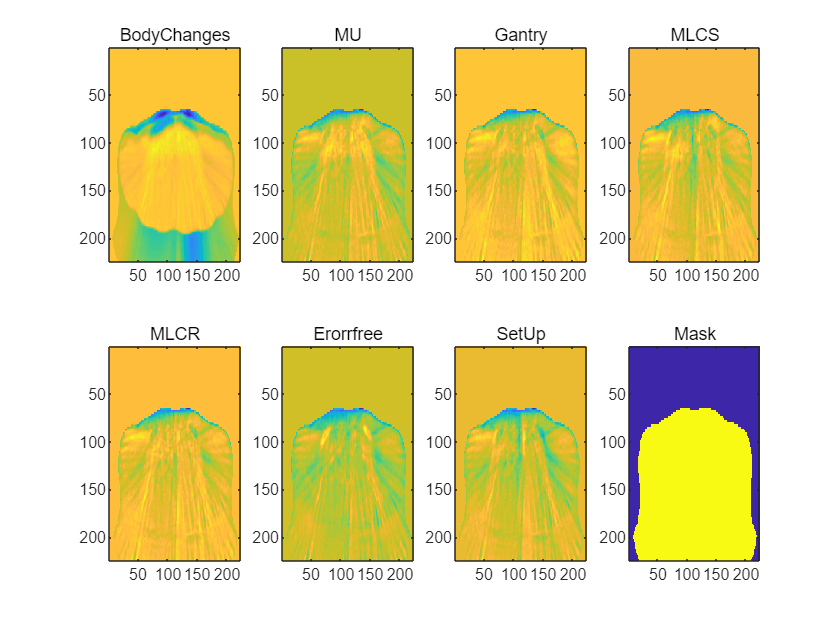

%可视化验证
%测试例 显示不同分类差异图像
%BODYfile
BDname = "p1-body1-"+ID+".mat";
BDfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BodyChanges', BDname);
BDTEST = load(BDfile);
BDVolume = BDTEST.Diff_interp; %Body变化测试图像
%BDVolume =permute(BDVolume,[2,3,1]);

%MUfile
MUname = "MU5%-"+ID+".mat";
MUfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MU', MUname);
MUTEST = load(MUfile);
MUVolume = MUTEST.Diff_interp; %MU测试图像
%MUVolume =permute(MUVolume,[2,3,1]);


%Gantryfile
GNname = "p1-0.4G-"+ID+".mat";
GNfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\Gantry', GNname);
GNTEST = load(GNfile);
GNVolume = GNTEST.Diff_interp; %GN测试图像
%GNVolume =permute(GNVolume,[2,3,1]);


%MLCSfile
MLCSname = "p1-1X2F-"+ID+".mat";
MLCSfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCS', MLCSname);
MLCSTEST = load(MLCSfile);
MLCSVolume = MLCSTEST.Diff_interp; %MLC SYSTEM测试图像
%MLCSVolume =permute(MLCSVolume,[2,3,1]);


%MLCRfile
MLCRname = "p1-2X2R-"+ID+".mat";
MLCRfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCR', MLCRname);
MLCRTEST = load(MLCRfile);
MLCRVolume = MLCRTEST.Diff_interp; %MLC RADNOM测试图像
%MLCRVolume =permute(MLCRVolume,[2,3,1]);


%SETUP file
STname = "LAT-1mmR-"+ID+".mat";
STfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\SETUP', STname);
STTEST = load(STfile);
STVolume =STTEST.Diff_interp; %SET UP测试图像
%STVolume =permute(STVolume,[2,3,1]);

%ERRORFREE file
EFname = "P1-AXBW-"+ID+".mat";
EFfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\ErrorFree', EFname);
EFTEST = load(EFfile);
EFVolume = EFTEST.Diff_interp; %SET UP测试图像
%EFVolume =permute(EFVolume,[2,3,1]);

%Bladder file
%Blname = "P1-B1-"+ID+".mat";
%BLfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BladderChanges', Blname);
%BLTEST = load(BLfile);
%BLVolume = BLTEST.Diff_interp; %Bladder测试图像
%EFVolume =permute(EFVolume,[2,3,1]);

imgidx  = 50;%想要显示的层面
figure(1),  
subplot(2,4,1),imagesc(BDVolume(:,:,imgidx)),title("BodyChanges");...
subplot(2,4,2),imagesc(MUVolume(:,:,imgidx)),title("MU");...
subplot(2,4,3),imagesc(GNVolume(:,:,imgidx)),title("Gantry");...
subplot(2,4,4),imagesc(MLCSVolume(:,:,imgidx)),title("MLCS");...
subplot(2,4,5),imagesc(MLCRVolume(:,:,imgidx)),title("MLCR");...
subplot(2,4,6),imagesc(EFVolume(:,:,imgidx)),title("Erorrfree");...
subplot(2,4,7),imagesc(STVolume(:,:,imgidx)),title("SetUp");
%subplot(2,4,8),imagesc(BLVolume(:,:,imgidx)),title("Bladder");
subplot(2,4,8),imagesc(ROIMask(:,:,imgidx)),title("Mask");

## 计算理想计划差异分布，即已P1-AXB作为ORI进行差异剂量计算

folder_len = size(folders,1);%更新文件目录长度
%获得原始AXB的文件名
oriAXBfilename = char("RD." + ID + ".P1-AXB"+".dcm");  %需要抓取文件的文件名，string转换为char以便后续对比

for i = 1 : folder_len
    if strcmpi(folders(i).name,oriAXBfilename)
        filename = fullfile(folders(i).folder,folders(i).name);
        info_ori = dicominfo(filename);
        dose_ori = dicomread(filename);
        size_ori = size(dose_ori);
        %记住当前ori的行号信息
        ori_row_to_delete = i;
    end
end
folders(ori_row_to_delete) = [];  %删除当前的参考p1-orim的文件目录，只剩下其他RD文件

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%以理想的AXB作为ori
%更新后面剂量差异信息的文件命名格式  删除p1-AXB命名
FileName = ["LAT-1mmL";"LAT-1mmR";"Lng-1mmF";"Lng-1mmH";"Vrt-1mmA";"Vrt-1mmP"...
            ;"MU3%-";"MU3%";"MU5%-";"MU5%";"p1--0.2G";"p1--0.4G";"p1-0.2G";"p1-0.4G"...
            ;"p1--0.5X2F";"p1--1X2F";"p1-0.5X2F";"p1-1X2F";"p1-0.5X2R";"p1-1X2R";"p1-2X2R"...
            ;"p1-AXBW";"p1-AAA";"p1-body0.5";"p1-body1.5";"p1-body1";"P1-B0.5";"P1+B0.5";"P1-B1";"P1+B1"];
%"P1-B0.5";"P1+B0.5";"P1-B1";"P1+B1"  %头颈部的时候可以删除上述代码中的这部分内容

FileName_SIZE = size(FileName,1);%更新需要处理文件名数组的长度


%新建差异文件夹用于保存数据  该句多余可以省略
%newfile = "diff";
%newfilepath = fullfile(filepath,newfile);
%[status, msg, msgID] = mkdir(newfilepath);
folder_len = size(folders,1); %在更新获取文件长度

%%%开始读取文件剂量剂量差异
for i = 1 : folder_len
    newfile = fullfile(folders(i).folder,folders(i).name);%逐个读取逐个计算
    info_new = dicominfo(newfile);

    [crop_new,crop_ori,diff_info]=CROPDICOM(info_new,info_ori); 
    
    %裁剪数据
    fprintf("开始计算%s剂量差异分布!\n       \n",folders(i).name);

      %确保剂量量刻度是否一致
    dose_scale_ori = info_ori.DoseGridScaling;
    dose_scale_new = info_new.DoseGridScaling; 
    
    Dose_new = double(crop_new)*dose_scale_new;
    Dose_ori = double(crop_ori )*dose_scale_ori;

    dosediff = Dose_new - Dose_ori;

    %调用子函数 尺寸匹配重采样计算公共区域的差异剂量
    %[dosediff, diff_info] = cal_diff(info_ori, info_new);

    %%%%%———————————  形成224X224X224文件用于后期深度学习 —————————%%%%%
    %调用子函数，提取对应Rsinfo中Body结构内的剂量特征，并插值为224x224X224
    [~, Diff_interp,ROIMask] = ROI_extract(dosediff,diff_info,RSinfo);
    
    %ID = diff_info.PatientID;可以省略

    for j = 1:FileName_SIZE %遍历文件名
        if contains(folders(i).name,FileName(j),"IgnoreCase",true) %不包含大小写对比文件名
             matname = FileName(j)+'-'+ID+'-AXBori'+'.mat';
             
             %%7分类问题命名
             %%根据命名规则将对应的数据保存到训练数据集的文件地址中  
             if ismember(FileName(j),SETUP)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\SETUP";  %注意保存路径
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),MU)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MU";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),MLCR)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCR";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),MLCS)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCS";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),GANTRY)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\Gantry";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),ErrorFree)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\ErrorFree";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             elseif ismember(FileName(j),BodyChanges)
                 savefilepath="D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BodyChanges";
                 matfilename=fullfile(savefilepath,matname);
                 save(matfilename,"Diff_interp");
             else
                 fprintf("有文件无法解析或存储，请检查命名")
             end
        end
    end

    %%%%%————————  形成dcm文件用于3Dslicer后期组学处理  ——————————%%%%%
    dosediff = dosediff /info_ori.DoseGridScaling;  %根据刻度进行归一
    
    [rows,cols,slices] = size(dosediff); 
    
    dosediff = reshape(dosediff,[rows,cols,1, slices]); %形成4D矩阵 用于后期封装
    dosediff = int32(dosediff); %double转换为有符号类型

    %将差异剂量图封装成Dicom数据保存回去 用于3D slicer数据处理
     for j = 1 : FileName_SIZE   %获取需要保存的文件名数据长度
        if contains(folders(i).name,FileName(j),"IgnoreCase",true) %不包含大小写对比文件名
            diff_info.SeriesInstanceUID = dicomuid();
            diff_info.SeriesDescription = char(FileName(j)); %用于SD
            diff_info.SOPInstanceUID = dicomuid();
            diff_info.PixelRepresentation = 1; %表明为有符号的数据  相减有正有负
            dosename = FileName(j)+'-AXBori'+'.dcm';
            dosefilename = fullfile(newfilepath,dosename);
            dicomwrite(dosediff,dosefilename,diff_info,'CreateMode','copy');
        end
     end   
end

   109   183     1   114

   109   184     1   114

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度尺寸相同，使用原始维度!


 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.Lat-1mmL.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   185     1   114

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度尺寸相同，使用原始维度!


 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.Lat-1mmR.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   186     1   114

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度尺寸相同，使用原始维度!
 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.Lng-1mmF.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   186     1   114

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度尺寸相同，使用原始维度!
 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.Lng-1mmH.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1--0.2G1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1--0.4G1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1--0.5X2F--1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1--1X2F--1X2.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1-0.2G1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1-0.4G1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1-0.5X2F-0.6.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1-0.5X2R-0.6.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1-1X2F-1X2.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1-1X2R-1X1R1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   184     1   112

X维度有差异，进行裁剪!
Y维度尺寸相同，使用原始维度!
Z维度有差异，进行裁剪!
 -229.5000
 -115.0000
 -166.2500



开始计算RD.7572022097.P1-2X2R-2X1R1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   110   184     1   114

X维度有差异，进行裁剪!
Y维度有差异，进行裁剪!
Z维度尺寸相同，使用原始维度!


 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.P1-AAA.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   111   185     1   114

X维度有差异，进行裁剪!
Y维度有差异，进行裁剪!
Z维度尺寸相同，使用原始维度!
 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.P1-AXBW.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   183     1   114

两者尺寸相等无需裁剪


开始计算RD.7572022097.P1-MU3%-.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   183     1   114

两者尺寸相等无需裁剪


开始计算RD.7572022097.P1-MU3%.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   183     1   114

两者尺寸相等无需裁剪


开始计算RD.7572022097.P1-MU5%-.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   109   183     1   114

两者尺寸相等无需裁剪


开始计算RD.7572022097.P1-MU5%.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   145   179     1   112

X维度有差异，进行裁剪!
Y维度有差异，进行裁剪!
Z维度有差异，进行裁剪!
 -224.5000
 -112.5000
 -166.2500



开始计算RD.7572022097.P1-body0.5.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   145   179     1   112

X维度有差异，进行裁剪!
Y维度有差异，进行裁剪!
Z维度有差异，进行裁剪!
 -224.5000
 -112.5000
 -166.2500



开始计算RD.7572022097.P1-body1.5.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   145   179     1   112

X维度有差异，进行裁剪!
Y维度有差异，进行裁剪!
Z维度有差异，进行裁剪!
 -224.5000
 -112.5000
 -166.2500



开始计算RD.7572022097.P1-body1.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   111   186     1   114

X维度有差异，进行裁剪!
Y维度有差异，进行裁剪!
Z维度尺寸相同，使用原始维度!


 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.Vrt-1mmA.dcm剂量差异分布!
       


坐标系一致

   109   183     1   114

   110   186     1   114

X维度有差异，进行裁剪!
Y维度有差异，进行裁剪!
Z维度尺寸相同，使用原始维度!


 -229.5000
 -115.0000
 -168.7500



开始计算RD.7572022097.Vrt-1mmP.dcm剂量差异分布!
       


坐标系一致

## 计算AXBW-AAA的差异剂量分布

%获得原始AXB的文件名
AXBWfilename = "RD." + ID + ".P1-AXBW"+".dcm";  %需要抓取文件的文件名，string转换为char以便后续对比
AAAfilename = "RD." + ID + ".P1-AAA"+".dcm";  %需要抓取文件的文件名，string转换为char以便后续对比

filepath = folders.folder;

%读取AXBW文件
newfile = fullfile(filepath,AXBWfilename);
info_new = dicominfo(newfile);

ori_file = fullfile(filepath,AAAfilename);
info_ori = dicominfo(ori_file);

fprintf("开始计算%s剂量差异分布!\n       \n",'AXBW-AAAori');
%调用子函数 尺寸匹配重采样计算公共区域的差异剂量
[crop_new,crop_ori,diff_info] = CROPDICOM(info_new,info_ori); 
%确保剂量量刻度是否一致
dose_scale_ori = info_ori.DoseGridScaling;
dose_scale_new = info_new.DoseGridScaling; 
    
Dose_new = double(crop_new)*dose_scale_new;
Dose_ori = double(crop_ori )*dose_scale_ori;
 
dosediff = Dose_new - Dose_ori;

%%%%%———————————  形成224X224X224文件用于后期深度学习 —————————%%%%%
%调用子函数，提取对应Rsinfo中Body结构内的剂量特征，并插值为224x224X224
[~, Diff_interp,ROIMask] = ROI_extract(dosediff,diff_info,RSinfo);
%需要存储的名字
matname = "AXBW-AAAori-"+ID+".mat";
savefilepath = "D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\ErrorFree";
matfilename = fullfile(savefilepath,matname);
save(matfilename, "Diff_interp");

%%%%%————————  形成dcm文件用于3Dslicer后期组学处理  ——————————%%%%%
dosediff = dosediff /info_ori.DoseGridScaling;  %根据刻度进行归一    
[rows,cols,slices] = size(dosediff);     
dosediff = reshape(dosediff, [rows,cols,1, slices]); %形成4D矩阵 用于后期封装
dosediff = int32(dosediff); %double转换为有符号类型

%将差异剂量图封装成Dicom数据保存回去 用于3D slicer数据处理
diff_info.SeriesInstanceUID = dicomuid();
diff_info.SeriesDescription = char("AXBW-AAAori"); %用于SD %必须用char类型 string类型可能会报错
diff_info.SOPInstanceUID = dicomuid();
diff_info.PixelRepresentation = 1; %表明为有符号的数据  相减有正有负
dosename = strcat('AXBW-AAAori','.dcm');
dosefilename = fullfile(newfilepath, dosename);
dicomwrite(dosediff,dosefilename, diff_info, 'CreateMode', 'copy');

## 计算Bladder的差异剂量分布


%头颈部请注释后续代码

%{
info_Bori = dicominfo(fullfile(filepath,oriAXBfilename));

%更新后面剂量差异信息的文件命名格式  删除p1-AXB命名
FileName = ["P1-B0.5";"P1+B0.5";"P1-B1";"P1+B1"];

FileName_SIZE = size(FileName,1);%更新需要处理文件名数组的长度

filepath = folders.folder;

%逐个读取AXBW文件
for i = 1:FileName_SIZE
    %获得Bladder外扩的文件名
    Bladder_filename = "RD." + ID + "."+ FileName(i) + ".dcm";  %需要抓取文件的文件名，string转换为char以便后续对比

    %获取完整路径
    newfile = fullfile(filepath,Bladder_filename);
    info_new = dicominfo(newfile);

    fprintf("开始计算%s剂量差异分布!\n       \n",FileName(i));

    %调用子函数 尺寸匹配重采样计算公共区域的差异剂量
    [crop_new,crop_Bori,diff_info] = CROPDICOM(info_new,info_Bori); 

    %确保剂量量刻度是否一致
    dose_scale_Bori = info_Bori.DoseGridScaling;
    dose_scale_new = info_new.DoseGridScaling; 
    
    Dose_new = double(crop_new) * dose_scale_new;
    Dose_Bori = double(crop_Bori ) * dose_scale_Bori;
 
    dosediff = Dose_new - Dose_Bori;

    %%%%%———————————  形成224X224X224文件用于后期深度学习 —————————%%%%%
    %调用子函数，提取对应Rsinfo中Body结构内的剂量特征，并插值为224x224X224
    [~, Diff_interp,ROIMask] = ROI_extract(dosediff,diff_info,RSinfo);
    
    %需要存储的名字
    matname =  FileName(i)+"-AXBori-"+ID+".mat";
    savefilepath = "D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BladderChanges";
    matfilename = fullfile(savefilepath,matname);
    save(matfilename, "Diff_interp");

    %%%%%————————  形成dcm文件用于3Dslicer后期组学处理  ——————————%%%%%
    dosediff = dosediff /info_ori.DoseGridScaling;  %根据刻度进行归一    
    [rows,cols,slices] = size(dosediff);     
    dosediff = reshape(dosediff,[rows,cols,1, slices]); %形成4D矩阵 用于后期封装
    dosediff = int32(dosediff); %double转换为有符号类型

    %将差异剂量图封装成Dicom数据保存回去 用于3D slicer数据处理
    diff_info.SeriesInstanceUID = dicomuid();
    diff_info.SeriesDescription = char(FileName(i)); %用于SD
    diff_info.SOPInstanceUID = dicomuid();
    diff_info.PixelRepresentation = 1; %表明为有符号的数据  相减有正有负
    dosename = FileName(i)+"-AXBori.dcm";
    dosefilename = fullfile(newfilepath,dosename);
    dicomwrite(dosediff,dosefilename,diff_info,'CreateMode','copy');
end
%}


%可视化验证
%测试例 显示不同分类差异图像
%BODYfile
%ID='7572023008';
BDname = "p1-body1-"+ID+"-AXBori"+".mat";
BDfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BodyChanges', BDname);
BDTEST = load(BDfile);
BDVolume = BDTEST.Diff_interp; %Body变化测试图像
%BDVolume =permute(BDVolume,[2,3,1]);

%MUfile
MUname = "MU5%-"+ID+"-AXBori"+".mat";
MUfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MU', MUname);
MUTEST = load(MUfile);
MUVolume = MUTEST.Diff_interp; %MU测试图像
%MUVolume =permute(MUVolume,[2,3,1]);


%Gantryfile
GNname = "p1-0.4G-"+ID+"-AXBori"+".mat";
GNfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\Gantry', GNname);
GNTEST = load(GNfile);
GNVolume = GNTEST.Diff_interp; %GN测试图像
%GNVolume =permute(GNVolume,[2,3,1]);


%MLCSfile
MLCSname = "p1-1X2F-"+ID+"-AXBori"+".mat";
MLCSfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCS', MLCSname);
MLCSTEST = load(MLCSfile);
MLCSVolume = MLCSTEST.Diff_interp; %MLC SYSTEM测试图像
%MLCSVolume =permute(MLCSVolume,[2,3,1]);


%MLCRfile
MLCRname = "p1-2X2R-"+ID+"-AXBori"+".mat";
MLCRfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\MLCR', MLCRname);
MLCRTEST = load(MLCRfile);
MLCRVolume = MLCRTEST.Diff_interp; %MLC RADNOM测试图像
%MLCRVolume =permute(MLCRVolume,[2,3,1]);


%SETUP file
STname = "LAT-1mmR-"+ID+"-AXBori"+".mat";
STfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\SETUP', STname);
STTEST = load(STfile);
STVolume =STTEST.Diff_interp; %SET UP测试图像
%STVolume =permute(STVolume,[2,3,1]);

%ERRORFREE file
%EFname = "P1-AXBW-"+ID+"-AXBori"+".mat";
EFname = "AXBW-AAAori-"+ID+".mat";
EFfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\ErrorFree', EFname);
EFTEST = load(EFfile);
EFVolume = EFTEST.Diff_interp; %SET UP测试图像
%EFVolume =permute(EFVolume,[2,3,1]);

%Blname = "P1-B1-AXBori-"+ID+".mat";
%BLfile = fullfile('D:\医学物理\待投稿论文\Dosiomics\TESTData\Type-7-MAT\BladderChanges', Blname);
%BLTEST = load(BLfile);
%BLVolume = BLTEST.Diff_interp; %SET UP测试图像
%EFVolume =permute(EFVolume,[2,3,1]);

imgidx  = 100;%想要显示的层面
figure(2),  
subplot(2,4,1),imagesc(BDVolume(:,:,imgidx)),title("BodyChanges");...
subplot(2,4,2),imagesc(MUVolume(:,:,imgidx)),title("MU");...
subplot(2,4,3),imagesc(GNVolume(:,:,imgidx)),title("Gantry");...
subplot(2,4,4),imagesc(MLCSVolume(:,:,imgidx)),title("MLCS");...
subplot(2,4,5),imagesc(MLCRVolume(:,:,imgidx)),title("MLCR");...
subplot(2,4,6),imagesc(EFVolume(:,:,imgidx)),title("Erorrfree");...
subplot(2,4,7),imagesc(STVolume(:,:,imgidx)),title("SetUp");
%subplot(2,4,8),imagesc(BLVolume(:,:,imgidx)),title("Bladder");
subplot(2,4,8),imagesc(ROIMask(:,:,imgidx)),title("Mask");

imgidx  = 150;%想要显示的层
figure(10),imagesc(ROIMask(:,:,imgidx)),title("Mask");